clear all;
f = @(x) x(1)-(4.*(x(1)+x(2)).*exp(-x(1).^2 - x(2).^2)+0.1).^2

f = function_handle with value:
    @(x)x(1)-(4.*(x(1)+x(2)).*exp(-x(1).^2-x(2).^2)+0.1).^2


f_odwr = @(x) -f(x);
f_due = @(x1, x2) x1-(4.*(x1+x2).*exp(-x1.^2 - x2.^2)+0.1).^2

f_due = function_handle with value:
    @(x1,x2)x1-(4.*(x1+x2).*exp(-x1.^2-x2.^2)+0.1).^2


f_wrap = @(x) f_due(x(1, :), x(2, :))

f_wrap = function_handle with value:
    @(x)f_due(x(1,:),x(2,:))



[X,Y] = meshgrid(-2:.05:2);
Z = f_due(X, Y)

Z =    -2.0090   -1.9588   -1.9085   -1.8582   -1.8079   -1.7576   -1.7072   -1.6568   -1.6063   -1.5558   -1.5053   -1.4548   -1.4042   -1.3536   -1.3031   -1.2525   -1.2020   -1.1515   -1.1010   -1.0507   -1.0004   -0.9502   -0.9000   -0.8500   -0.8001   -0.7502   -0.7004   -0.6507   -0.6011   -0.5514   -0.5018   -0.4522   -0.4025   -0.3527   -0.3029   -0.2530   -0.2030   -0.1529   -0.1027   -0.0525   -0.0022    0.0482    0.0986    0.1489    0.1993    0.2496    0.2998    0.3500    0.4000    0.4499
   -2.0088   -1.9585   -1.9082   -1.8579   -1.8076   -1.7571   -1.7067   -1.6562   -1.6057   -1.5551   -1.5046   -1.4540   -1.4034   -1.3527   -1.3022   -1.2516   -1.2011   -1.1507   -1.1004   -1.0501   -1.0000   -0.9500   -0.9002   -0.8505   -0.8009   -0.7514   -0.7020   -0.6527   -0.6035   -0.5542   -0.5049   -0.4556   -0.4062   -0.3567   -0.3070   -0.2571   -0.2071   -0.1569   -0.1066   -0.0561   -0.0055    0.0452    0.0960    0.1467    0.1975    0.2482    0.2988    0.3493    0.3997    0

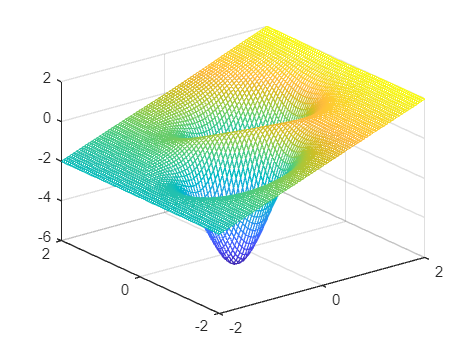

mesh(X,Y,Z)


P1= [-1,-1];
P2= [0,0];
P3= [3,3];
P4= [-0.8,1];
P5= [-2,-1];

s = 0.5;  %  długość kroku

alpha = 0.5;  % zmniejszenie kroku po niepowodzeniu

epsilon = 1e-6;  % dokładność

x = HJ(f, P1, s, alpha, epsilon, 2)

x =    -0.5000   -0.5000


x = HJ(f, P2, s, alpha, epsilon, 2)

x =     0.5000    0.5000


x = HJ(f, P3, s, alpha, epsilon, 2)

x =    -0.5000   -0.5000


x = HJ(f, P4, s, alpha, epsilon, 2)

x =    -0.0667    1.7333


x = HJ(f, P5, s, alpha, epsilon, 2)

x =    -1.9688   -0.9688


function [x] = HJ_try(f, x, s, baza)
    for e = baza
        if f(x + s*e) < f(x)
            x = x + s;
        else
            if f(x - s*e) < f(x)
                x = x - s;
            end %if
        end %if
    end %while
end %HJ_try


function [x] = HJ(f, x, s, alpha, epsilon, dim)
    baza = eye(dim, dim);
    while s>epsilon
        x_b = x;
        x = HJ_try(f, x_b, s, baza);
        if f(x) < f(x_b)
    
            while f(x) < f(x_b)
            xx_b = x_b;
            x_b = x;
            x = 2*x_b - xx_b;
            x = HJ_try(f, x, s, baza);
            end %while
            
            x = x_b;
    
        else %if
            s = alpha * s;
            
        end %if
    end %while
    x = x_b;
end %HJ_try